# Ejercicios raíces

5.7 Determine the roots of f (x) = −12 − 21*x + 18*x^2 − 2.75*x^3 graphically. In addition, determine the first root of the function with bisection (linear interpolation and Newton-Raphson)

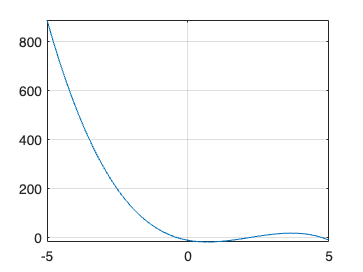

f = @(x) -12 - 21*x + 18*x.^2 - 2.75*x.^3;

fplot(f);
grid on;

This plot indicates that roots are located at about –0.4, 2.25 and 4.7. La primera raíz está en [-1,0].

Para -0.4:

[x, i] = biseccion(f, -1, 0)

x = -0.4147

i = 54

[x, i] = interpolacionLineal(f, -1, 0)

x = -0.4147

i = 55

[x, i] = newtonRaphson(f, -1, 0)

x = -0.4147

i = 4

Para 2.25:

[x, i] = biseccion(f, 2, 2.5)

x = 2.2198

i = 50

[x, i] = interpolacionLineal(f, 2, 2.5)

x = 2.2198

i = 55

[x, i] = newtonRaphson(f, 2, 2.5)

x = 2.2198

i = 3

Para 4.7:

[x, i] = biseccion(f, 4.5, 5)

x = 4.7403

i = 47

[x, i] = interpolacionLineal(f, 4.5, 5)

x = 4.7403

i = 16

[x, i] = newtonRaphson(f, 4.5, 5)

x = 4.7403

i = 3

5.8 Locate the first nontrivial root of sin(x) = x^2 where x is in radians. Use a graphical technique and a numerical algorithm..

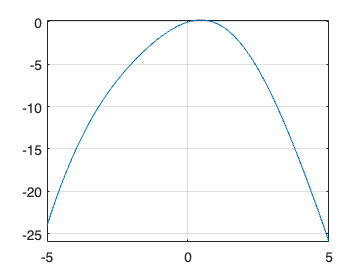

f = @(x) sin(x) - x.^2;

fplot(f);
grid on;

`La raíz trivial es 0; la no trivial está en [0.5, 1].`

[x, i] = biseccion(f, 0.5, 1)

x = 0.8767

i = 51

5.9 Determine the positive real root of ln(x^2) = 0.7 (a) graphically, (b) using a numerical method, with initial guess in xl = 0.5 and xu = 2

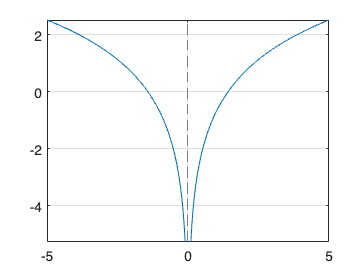

f = @(x) log(x.^2) - 0.7;

fplot(f);
grid on;

`La solución se encuentra en [1, 1.5].`

[x, i] = biseccion(f, 1, 1.5)

x = 1.4191

i = 51

`Ahora, con xl = 0.5 and xu = 2:`

[x, i] = biseccion(f, 0.5, 2)

x = 1.4191

i = 53

`Sí encuentra la raíz positiva pero en más iteraciones.`

Escribe aquí las funciones bisección, interpolación lineal y Newton-Raphson.

function [xr, i] = biseccion(f, xl, xu)
    if sign(f(xl)) * sign(f(xu)) >= 0
        error('f(a) * f(b) < 0 no se satisface.')
    end
    
    MAX_ITER = 55;
    TOLER = eps;
    xr = (xl + xu) / 2; 
    fx = f(xr);
    i = 0;
    
    while fx ~= 0 && abs((xu - xl) / xu) > TOLER && i < MAX_ITER
        if sign(f(xl)) == sign(fx)
            xl = xr;
        else
            xu = xr;
        end 
        xr = (xl + xu) / 2;
        fx = f(xr);
        i = i + 1;
    end
end


function [x, i] = interpolacionLineal(f, a, b)
    if sign(f(a)) * sign(f(b)) >= 0
        error('f(a) * f(b) < 0 no se satisface.')
    end
    
    MAX_ITER = 55;
    TOLER = eps;
    fa = f(a);
    x = b - f(b) * (b - a) / (f(b) - fa);
    fx = f(x);
    i = 0;
    
    while abs((b - a) / x) > TOLER && fx ~= 0 && i < MAX_ITER        
        if sign(fa) == sign(fx)
            a = x;
            fa = f(a);
        else
            b = x;
        end 
        x = b - f(b) * (b - a) / (f(b) - fa);
        fx = f(x);
        i = i + 1;
    end
end


function [x, i] = newtonRaphson(f, a, b)
    REL_TOL = sqrt(eps);
    MAX_ITER = 53;
    x = (a + b) / 2;
    df = matlabFunction(diff(sym(f)));
    
    if nargin(df) == 0
        df = @(x) df();
    end
    
    i = 0;
    flag = true;
    while flag
        xp = x;
        x = xp - f(xp) / df(xp);
        i = i + 1;
        flag = i < MAX_ITER && abs((x - xp) / x) > REL_TOL;     
    end
end